# Example: COVID-2019 data for South korea  (22-Jan-2020 - )

I am taking some data from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 04-Apr-2020




Location = 'Korea';


try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1);
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1);
    indD = find(contains(tableDeaths.CountryRegion,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find([searchLoc{:}]==1);
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find([searchLoc{:}]==1);
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indD = find([searchLoc{:}]==1);
    
    
end

tableRecovered(indR,1:2)

ans = 1×2 table
    ProvinceState    CountryRegion 
    _____________    ______________

      <missing>      "Korea, South"


indR = indR(1)

indR = 139



Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= round(0.025*max(Confirmed));
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end


Npop= 60e6; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
QT_guess = 21; % quarantine time in days
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    1/QT_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     4.02144e+10                      2.06e+12
     1         18     6.66716e+09      0.0439725       2.84e+11      
     2         27     1.38037e+09      0.0523603       4.47e+10      
     3         36     4.51969e+08      0.0802133       8.96e+09      
     4         45     2.78731e+08       0.117731       1.69e+09      
     5         54     1.63921e+08      0.0960387       2.06e+09      
     6         63     1.59312e+08     0.00524496       2.02e+09      
     7         72     1.58092e+08      0.0007225       6.07e+08      
     8         81      1.0906e+08      0.0455127       7.79e+09      
     9         90     7.18421e+07       0.256969       4.27e+08      
    10         99     3.80713e+07      0.0375703       8.25e+09      
    11        108     2.07657e+07       0.244931       2.93e+08      
    12        117     2.07657e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(10)));
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

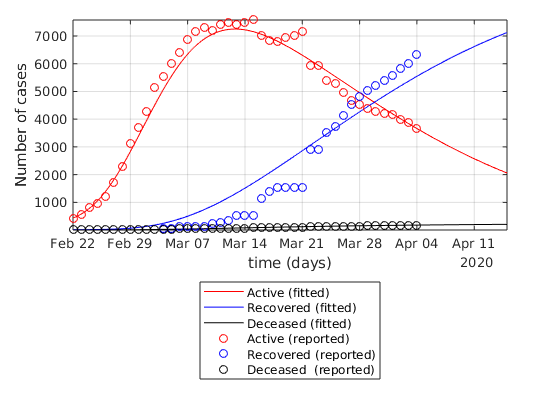

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Active (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
 set(gca,'yscale','lin')